## I. Decomposição de Sinais em Série de Fourier

**1. Determine as expressões de 𝑎𝑘 e 𝑏𝑘 correspondentes à representação do seguinte sinal em Série de Fourier: (ver guiao)**

**𝑥(𝑡) = ∑ 𝐴𝑘 cos(𝑘𝜔0𝑡 + 𝜑𝑘) =  ∑ 𝑎𝑘 cos(𝑘𝜔0𝑡) + ∑ 𝑏𝑘 sin(𝑘𝜔0𝑡)**

**Para k>0**

**𝑎𝑘 = 2/𝑇0 * ∫ 𝑥(𝑡) cos(𝑘𝜔0𝑡) 𝑑𝑡**

**𝑏𝑘 = 2/𝑇0 * ∫ 𝑥(𝑡) sin(𝑘𝜔0𝑡) 𝑑𝑡, **

**com 𝑇0 = 2𝜋/𝜔0**

**Para k=0**

**𝑎0 = 2/𝑇0 * ∫ 𝑥(𝑡)𝑑𝑡**

f0 = 1;
k = 10;
Fa = 100 %% Fa >= 2**f0

Fa = 100

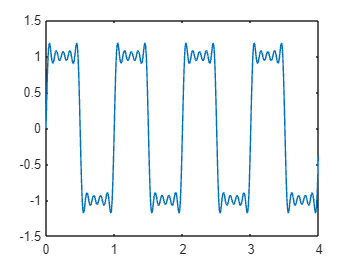


a = zeros(1,k+1);
b = zeros(1, k+1);
ind = 1:2:10;
b(2:2:end) = 4./(ind*pi);

[sinal, t] = SumFourier(1/Fa, f0, 4, a, b);
plot(t,sinal)

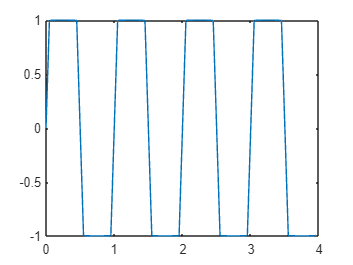



%% aproxima-se da função original
f0 = 1;
k = 500;
Fa = 2*(10*f0);

a = zeros(1,k+1);
b = zeros(1, k+1);
ind = 1:2:500;
b(2:2:end) = 4./(ind*pi);

[sinal, t] = SumFourier(1/Fa, f0, 4, a, b);
plot(t,sinal)


[ax, bx] = calcCoef(1/Fa,1/f0,x,k);

Unrecognized function or variable 'x'.

ax
bx




**3. Desenvolva uma função em MATLAB que calcule os coeficientes 𝑎𝑘 e 𝑏𝑘 de um sinal periódico 𝑥(𝑛). Essa função deverá receber como argumentos de entrada:**

**- 𝑇𝑎: Período de amostragem, em segundos;**

**- 𝑇0: Período do sinal, em segundos;**

**- 𝑥: Vetor (𝑁x1) com as amostras sucessivas do sinal a decompor (deverá ser passado um número inteiro de períodos deste sinal, não devendo o último período ficar truncado);**

**- 𝐾: Número de harmónicas a considerar na decomposição.**

function [ax, bx] = calcCoef(Ta,T0,x,k)
    N = T0/Ta;
    x1 = x(1:N);
    t = (0:N-1)*Ta;
    ak = zeros(1,k);
    ak(1) = mean(x1);
    bk = zeros(1,k);
    bk(1) = 0;
    for k= 2:k+1
        ak(k) = (2/N) * sum(x1.*cos(2*pi*(k-1)*f0*t));
        bk(k) = (2/N) * sum(x1.*sin(2*pi*(k-1)*f0*t));
    end
end

function [x,t] = SumFourier(Ta,f0,NP,ax,bx)
    T0 = 1/f0;
    t = 0:Ta:NP * T0-Ta;
    L = length(ax);
    x = zeros(1, length(t));
    for k= 1:L
        x = x+ax(k)*cos(2*pi*(k-1)*f0*t) + bx(k)*sin(2*pi*(k-1)*f0*t);
    end
end